# Lab 7 - Event selection optimization

Thomas Conaway

Lab Partners: Avi Soval, Jeff Jiang

clc; clear; close all;
% signal dataset is labelled higgs, background dataset is labeled "qcd"
% h5disp("higgs_100000_pt_1000_1200.h5");
% h5disp("qcd_100000_pt_1000_1200.h5");
signaldata1 = h5read("higgs_100000_pt_1000_1200.h5",'/higgs_100000_pt_1000_1200');
bgdata1 = h5read("qcd_100000_pt_1000_1200.h5",'/qcd_100000_pt_1000_1200');

## Problem 1

Stacked histogram for the mass feature variable, normalized to expected yield:

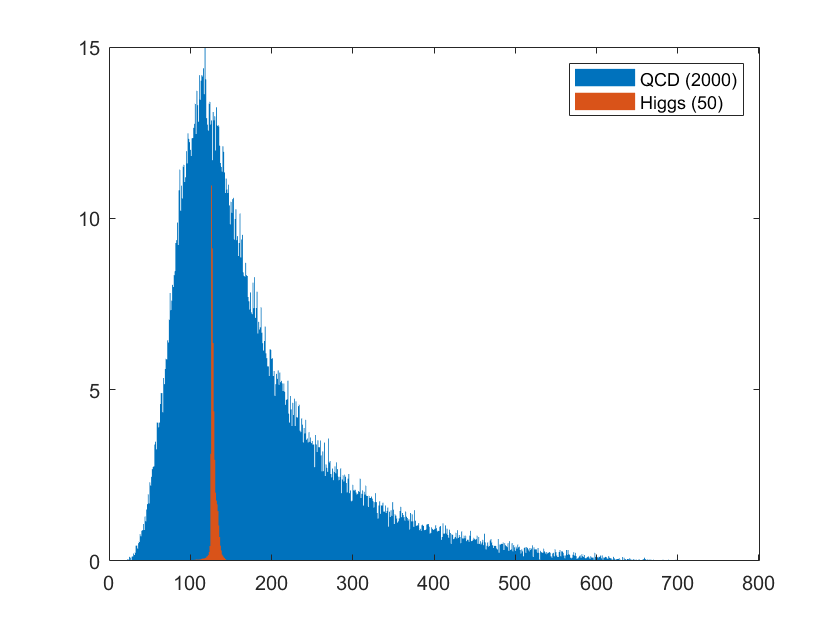

signal = signaldata1(4,:);
bg = bgdata1(4,:);
x = 0:800;
f1 = figure();
f2 = figure("Visible","off");
h = histogram(signal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
hold on;
h2 = histogram(bg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
hold off;
figure(f1);
% y = [h2.BinCounts;h.BinCounts]; % can use this to properly "stack" bars
% bar(h2.BinEdges(2:end),y.','stacked',"Edgecolor","none","BarWidth",1); % works! 
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
legend("QCD (2000)","Higgs (50)");
hold off;

Using Poisson statistics for significance calculation (*Do significance calculation using poisson with a mean of the expected value.)

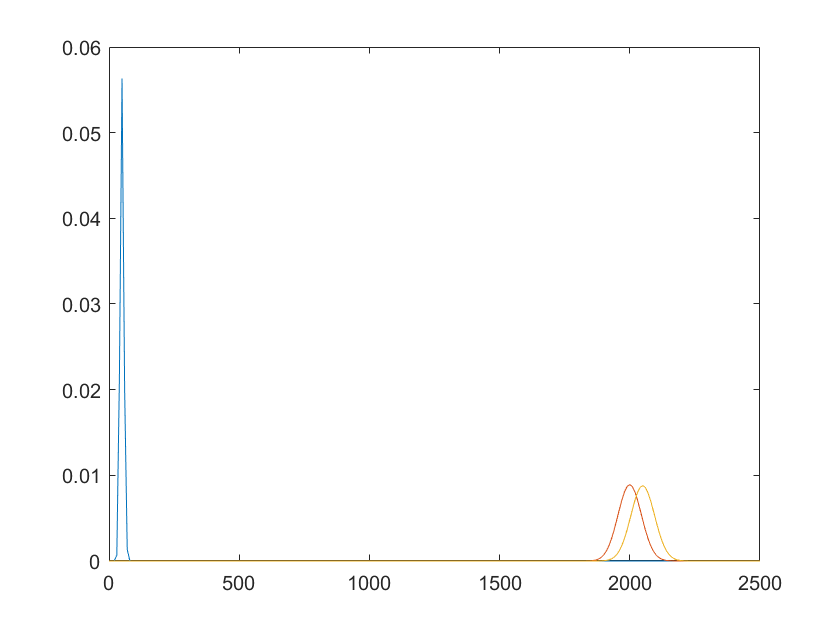

disthiggs = makedist("Poisson","lambda",50);
distqcd = makedist("Poisson","lambda",2000);
distcombo = makedist("Poisson","lambda",2050);
x = 0:10:2500;
plot(x,pdf(disthiggs,x));
hold on;
plot(x,pdf(distqcd,x));
plot(x,pdf(distcombo,x));
hold off;

Significance should refer here to the probability of background producing the event.

Significance calculation:

% by hand
[testval,testindex] = histcounts(bg,x);
testval = testval/sum(testval);
testsum = 0;
for k = testindex
    testsum = testsum + testval(k+1);
    if k >= 125
        break;
    end
end
testsum

testsum = 0.1076

sigma = abs(norminv(testsum))

sigma = 1.2394

% by fitted distribution
% prob = cdf(mydist3,125,'upper'); % may not be the right fit, poisson 120
% sigma = abs(norminv(prob))

Comparison to $N_{\mathrm{Higgs}} \;/\sqrt{\;N_{\mathrm{QCD}} }$:

50/sqrt(2000)

ans = 1.1180

Not equivalent. Should they be? *Yes, maybe. Is the point to say that the expression can be used to calculate significance? *I've now done a fair amount of searching and do believe that, yes, this describes the significance. $S/\sqrt{\;B}$.

## Problem 2

Will try cutting below 100 and above 145.

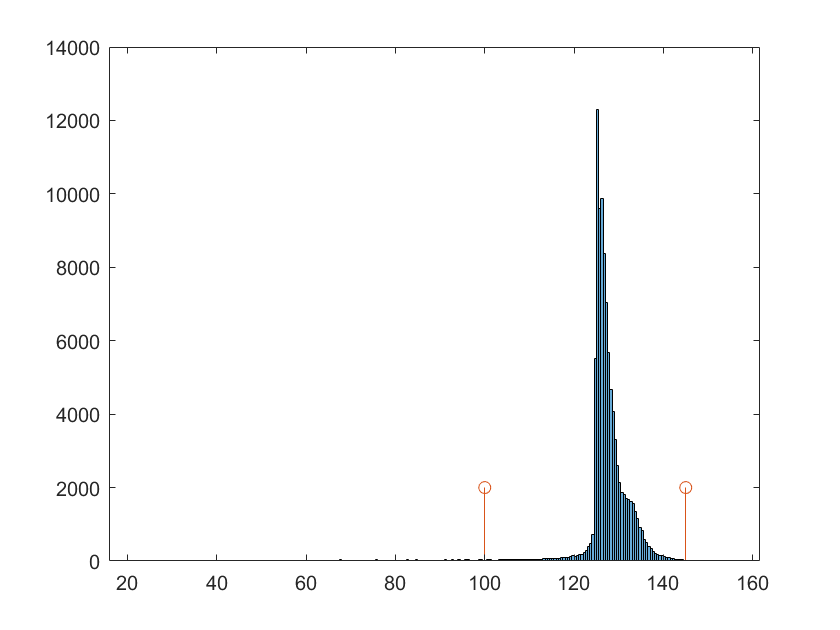

lowercut = 100;
uppercut = 145;
histogram(signal);
hold on;
stem([lowercut,uppercut],[2000,2000]);
hold off;

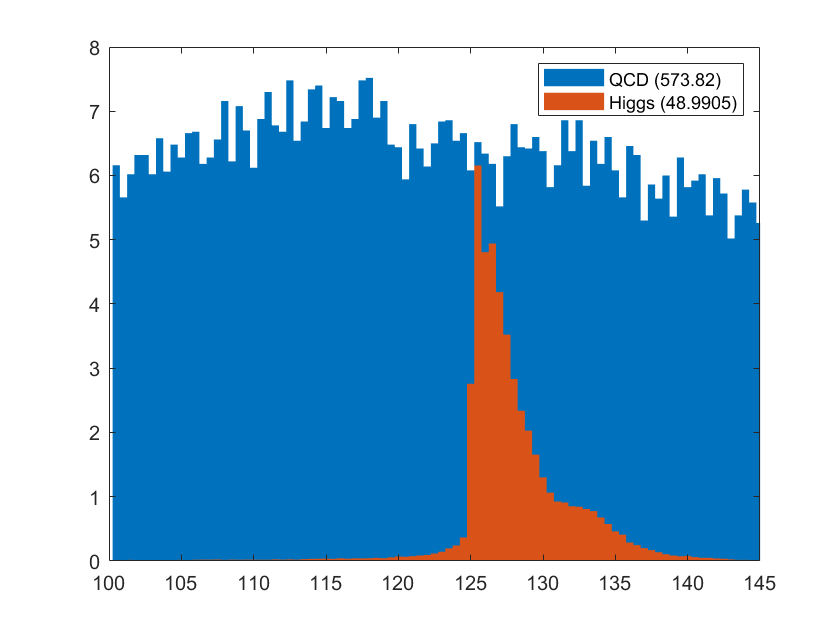

cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);

% plotting again:
f1 = figure();
f2 = figure("Visible","off");
stepsize = 0.5;
x = lowercut:stepsize:uppercut;

nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;

h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;

figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);

legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 2.0451

Try 124 and 130.

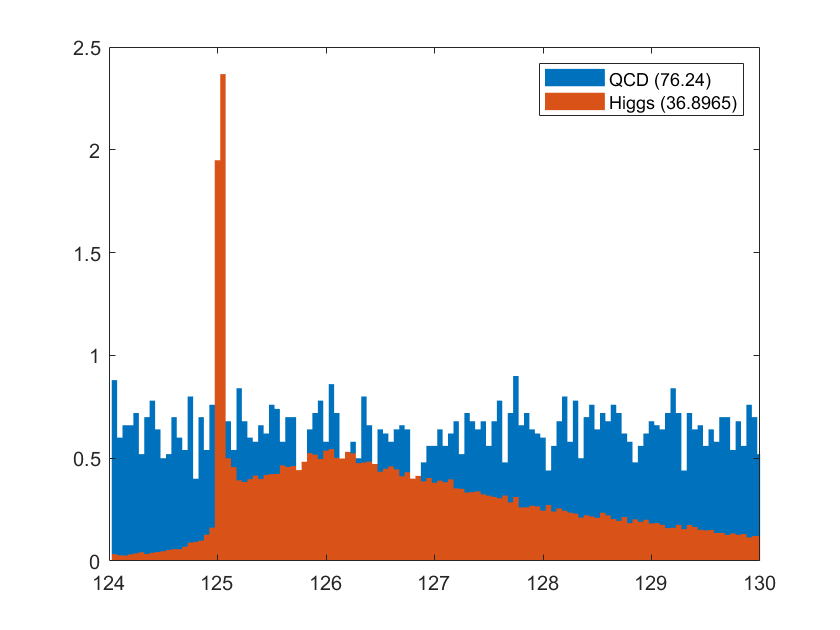

lowercut = 124;
uppercut = 130;
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);

% plotting again:
f1 = figure();
f2 = figure("Visible","off");
stepsize = 0.05;
x = lowercut:stepsize:uppercut;

nhiggs = numel(cutsignal)/numel(signal)*50;
nqcd = numel(cutbg)/numel(bg)*2000;

h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;

figure(f1);
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
hold on;
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);

legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
xlim([lowercut,uppercut]);
hold off;

nhiggs/sqrt(nqcd)

ans = 4.2257

Try only just those that are very close to 125.

lowercut = 124.99;
uppercut = 125.01;
%cutsignal = cutsignal(cutsignal < uppercut);
cutsignal = signal(signal < uppercut);
cutsignal = cutsignal(cutsignal > lowercut);
%cutbg = cutbg(cutbg < uppercut);
cutbg = bg(bg < uppercut);
cutbg = cutbg(cutbg > lowercut);

% plotting again:
f1 = figure();
f2 = figure("Visible","off");
stepsize = 0.001;
x = lowercut:stepsize:uppercut;

nhiggs = numel(cutsignal)/numel(signal)*50 % how many of the original 50 remain

nhiggs = 3.2850

nqcd = numel(cutbg)/numel(bg)*2000 % " " 2000 "

nqcd = 0.1800

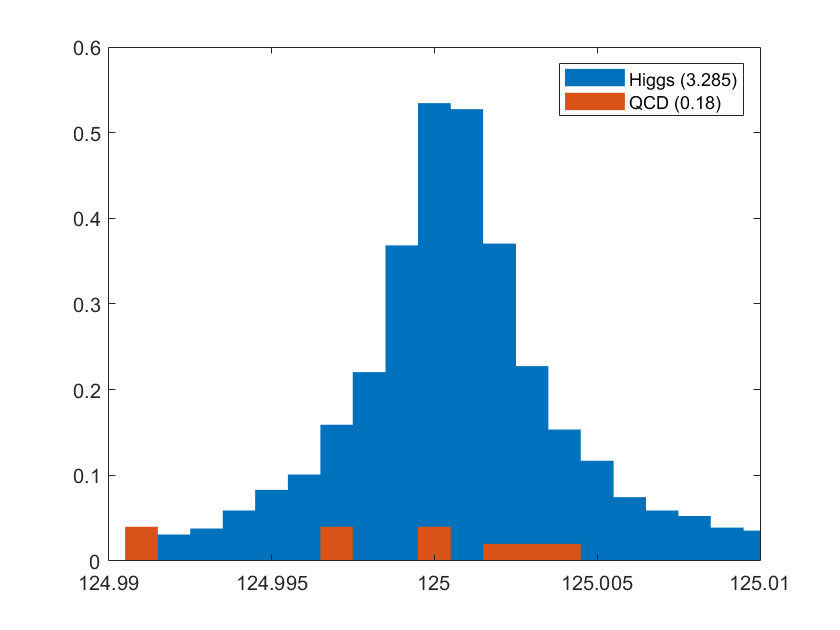


h = histogram(cutsignal,x,"Normalization","pdf");
h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
hold on;
h2 = histogram(cutbg,x,"Normalization","pdf");
h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
hold off;

figure(f1);
bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);

hold on;
bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);

legend("Higgs (" + nhiggs + ")","QCD (" + nqcd + ")");
xlim([lowercut,uppercut]);
hold off;

% swapped colors, fix later
nhiggs/sqrt(nqcd)

ans = 7.7428

Sets with the highest significance are the ones closest to the expected mass value of 125. May not mean anything because there are now gaps in the background distribution, so we're approaching the point where this counting method runs into trouble as it becomes possible to select cut regions with little to no background within. May need to rethink this approach and think purely in terms of distribution curve because the granularity is an issue.

Played around with some values and the highest I found was 7.7428 for when lower cut is 124.99 and upper cut is 125.01.

This is saying that in this narrow region most of the events are going to be signal.

## Problem 3

Stacked plots for the rest of the features:

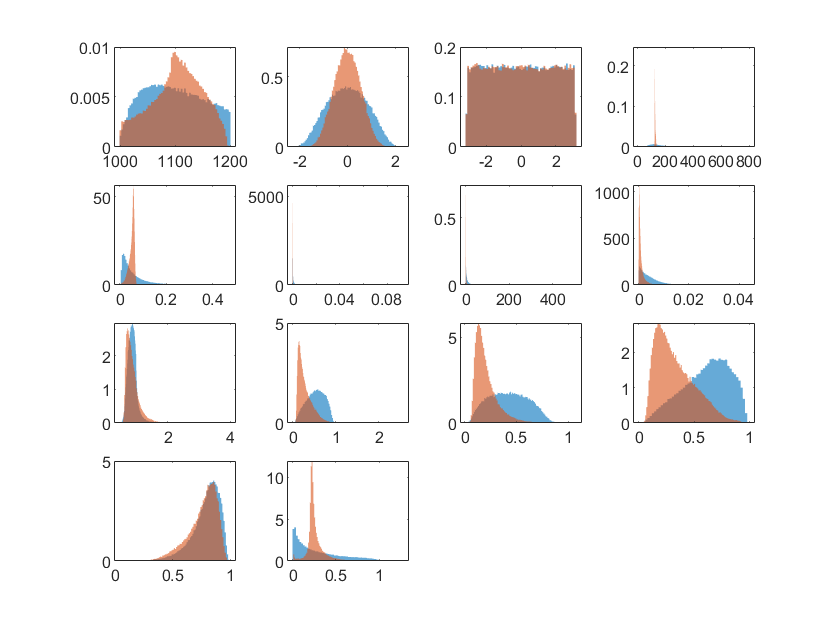

% to normalize or not normalize so as to show features at a glance? doing
% the 50 2000 thing makes them difficult to examine

% with standard normalization:
close all hidden;
for k = 1:14
    subplot(4,4,k);
    histogram(bgdata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold on;
    histogram(signaldata1(k,:),"EdgeColor",'none',"Normalization","pdf");
    hold off;
end

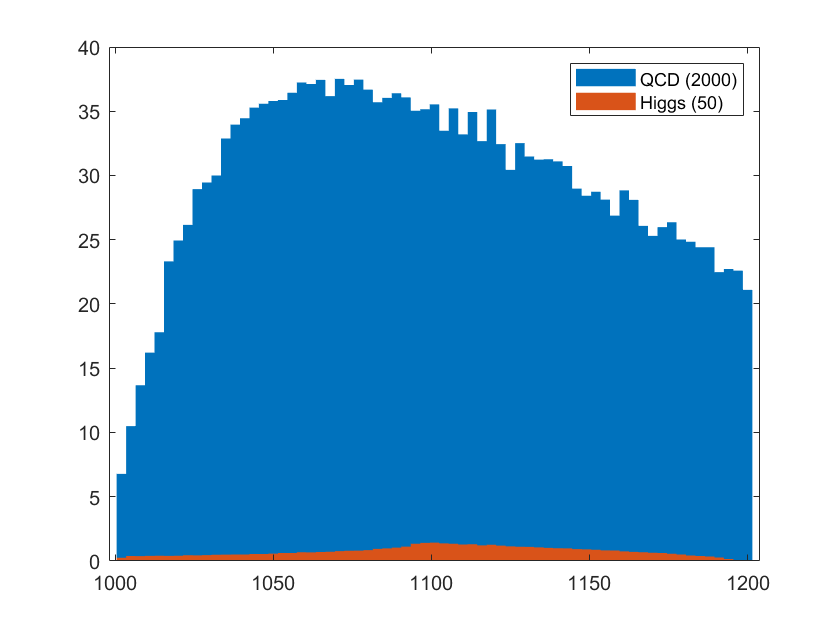

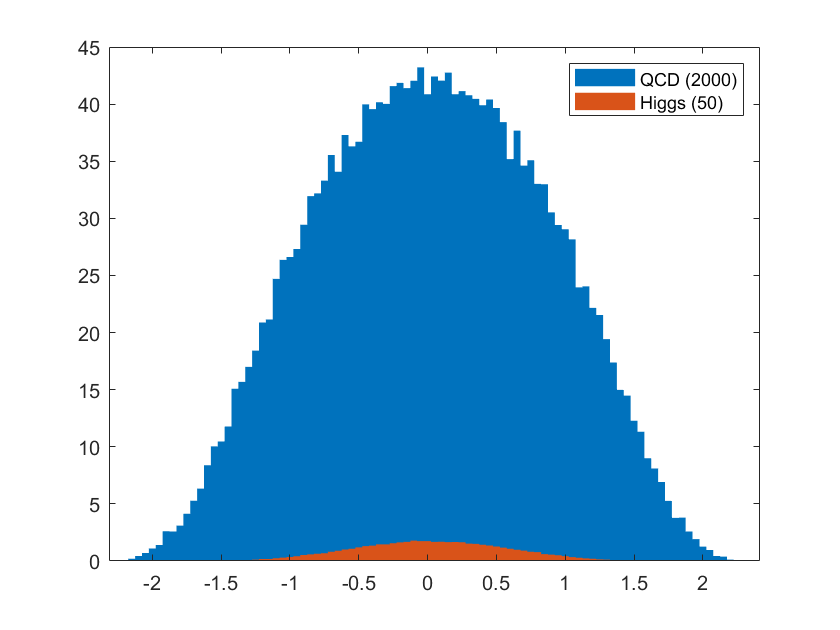

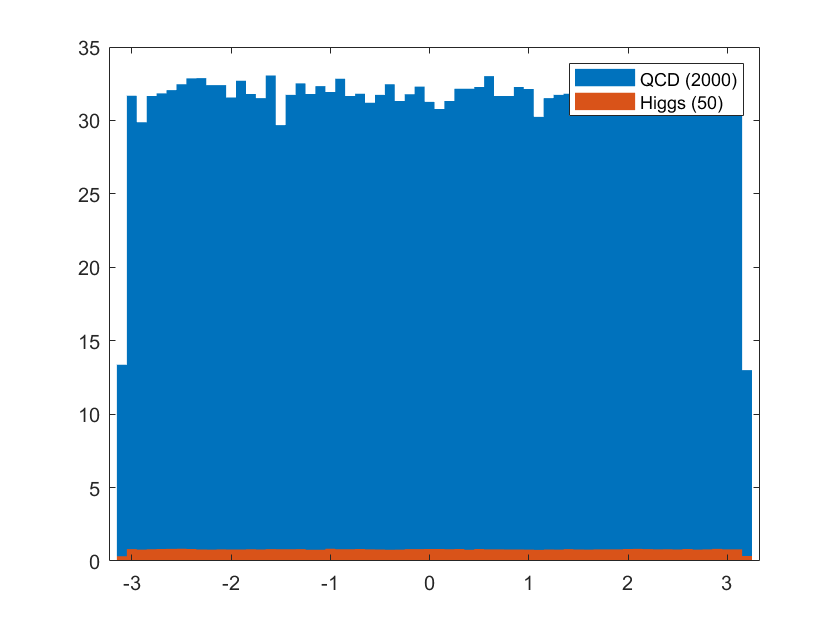

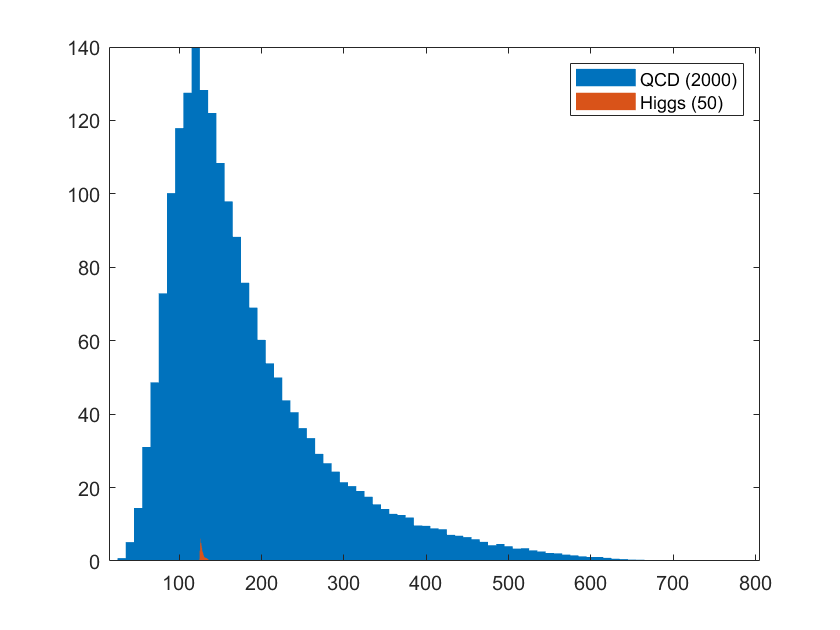

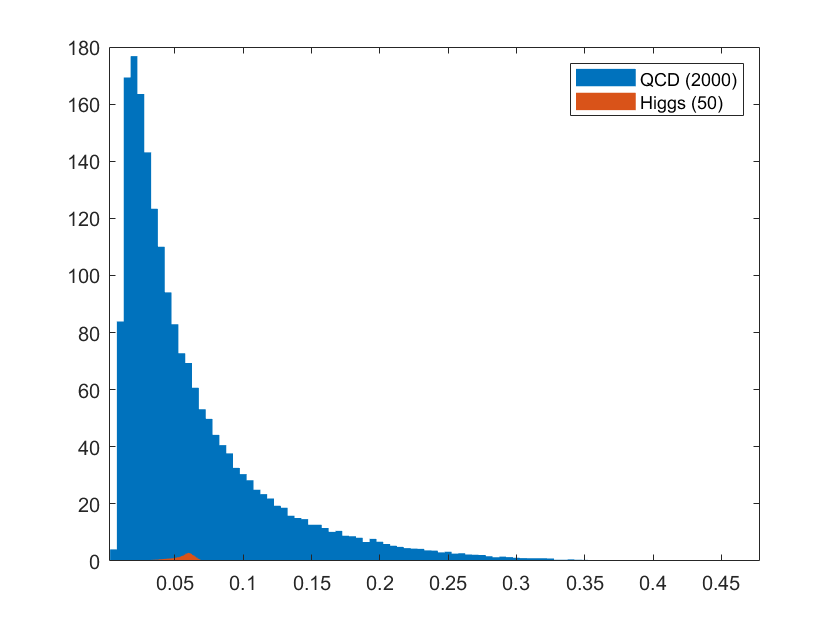

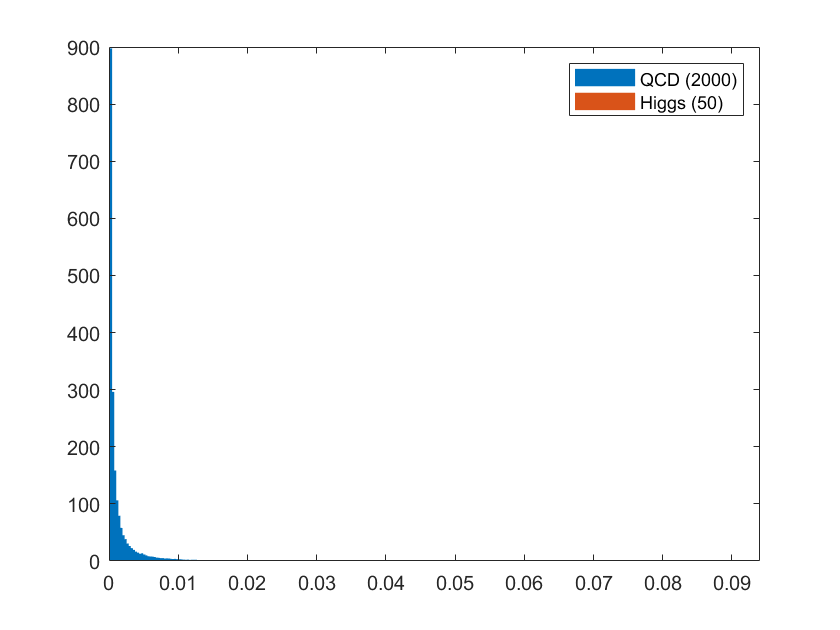

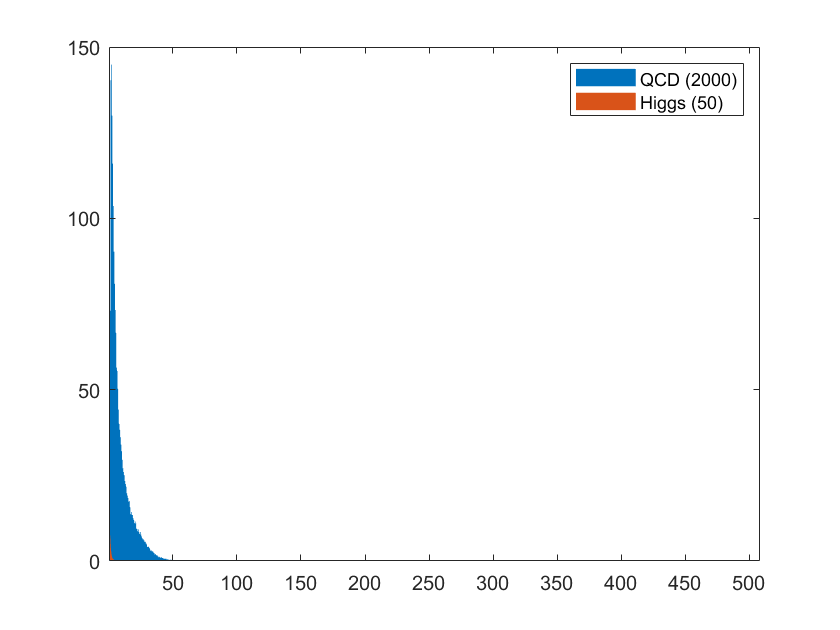

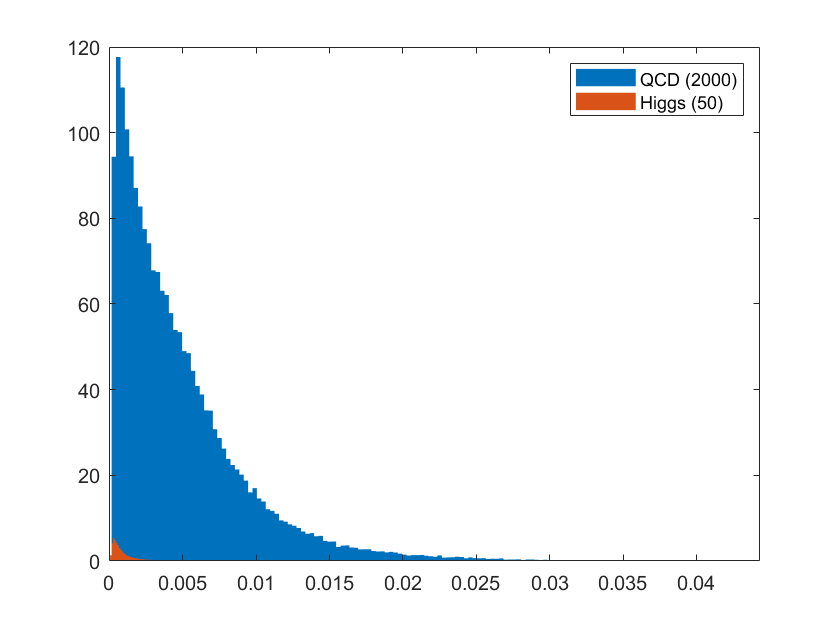

% these are with 50 2000 normalization:
for k = 1:14
    signal = signaldata1(k,:);
    bg = bgdata1(k,:);
    f1 = figure();
    f2 = figure("Visible","off");
    h = histogram(signal,"Normalization","pdf");
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * 50;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * 2000;
    hold off;
    
    %subplot(4,4,k);
    figure(f1);
    bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
    hold on;
    bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
    legend("QCD (2000)","Higgs (50)");
    hold off;
end

It would appear that there are a number of features that could make for good cuts, such as in ???.

Set B:

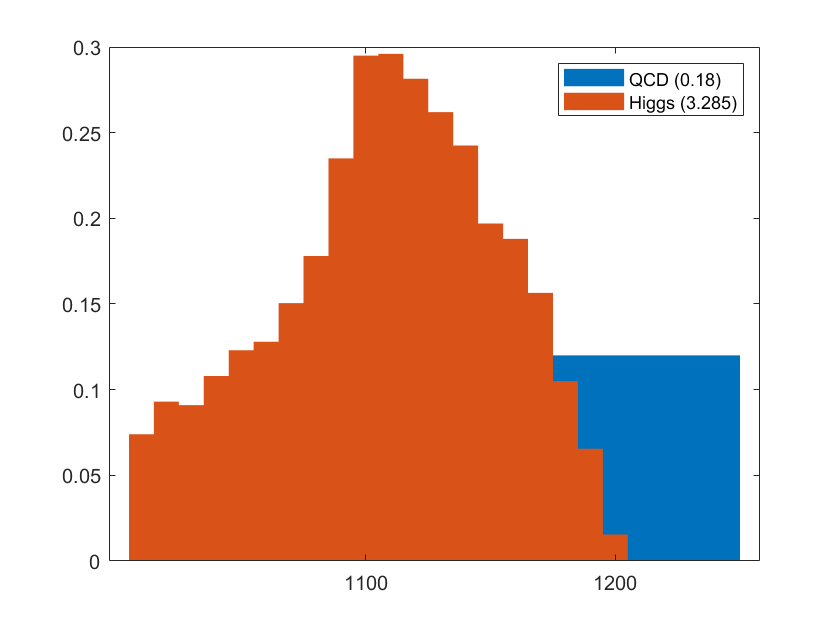

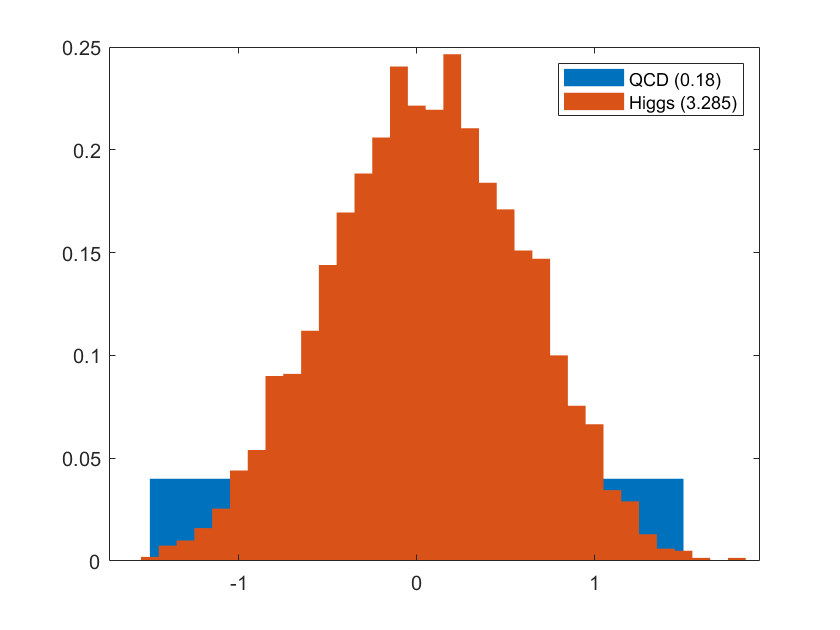

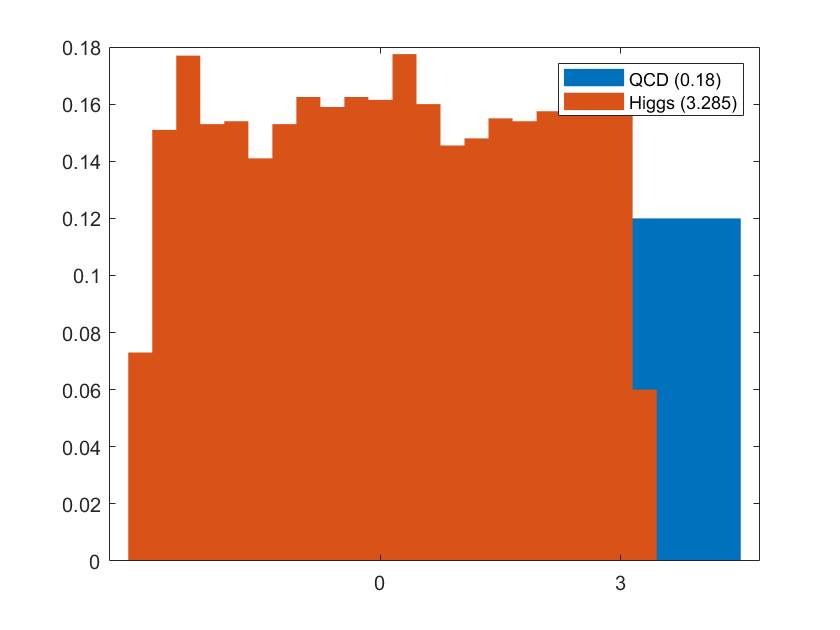

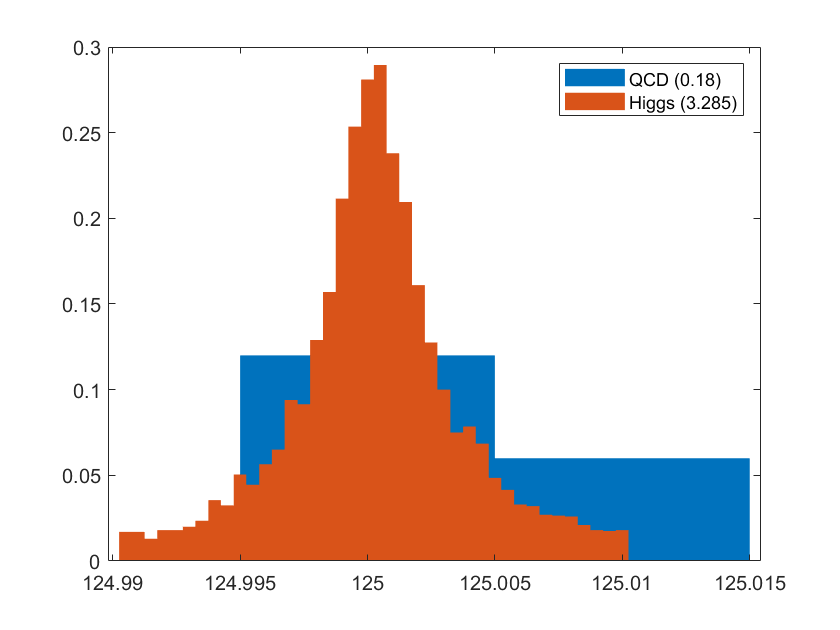

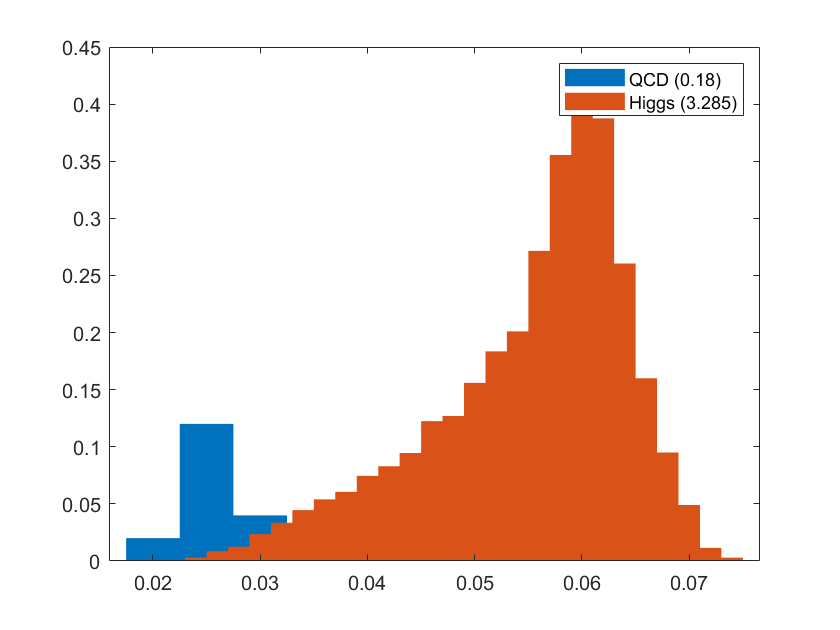

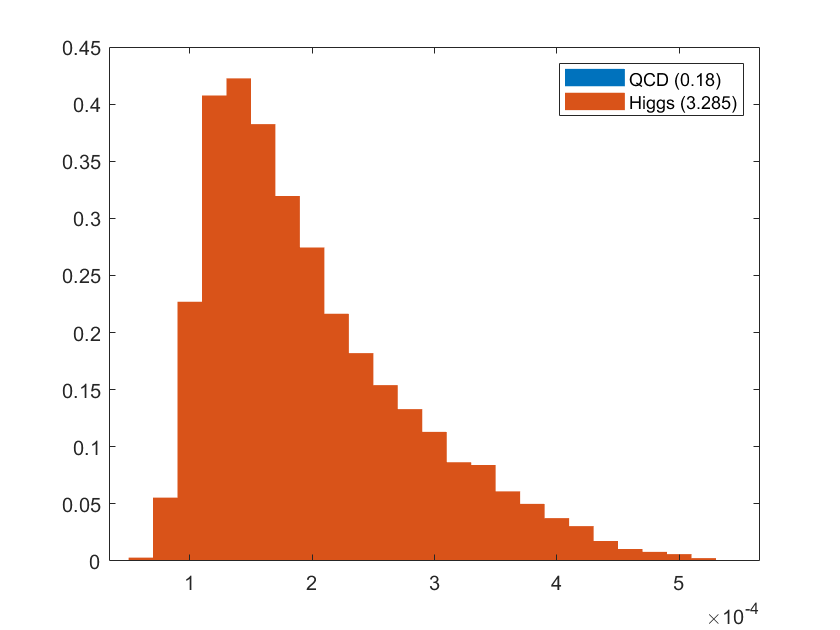

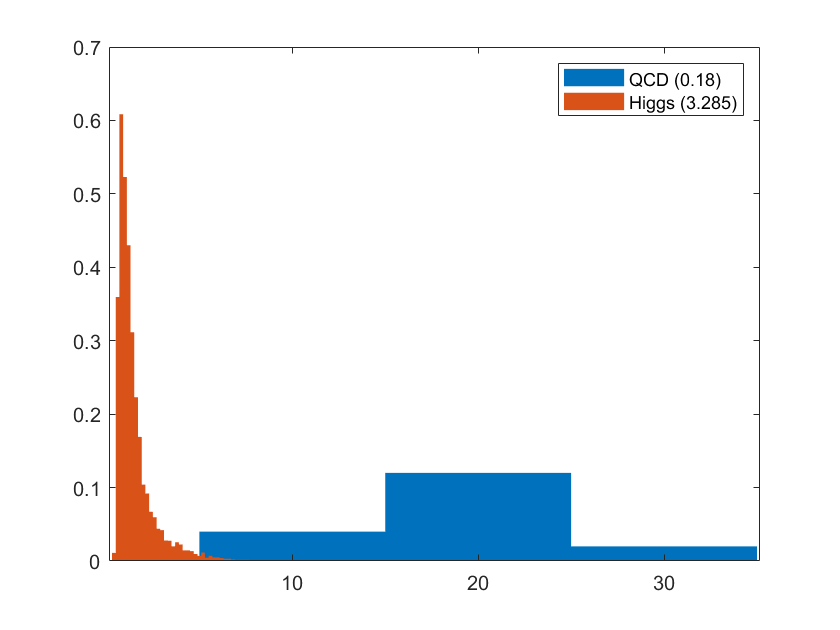

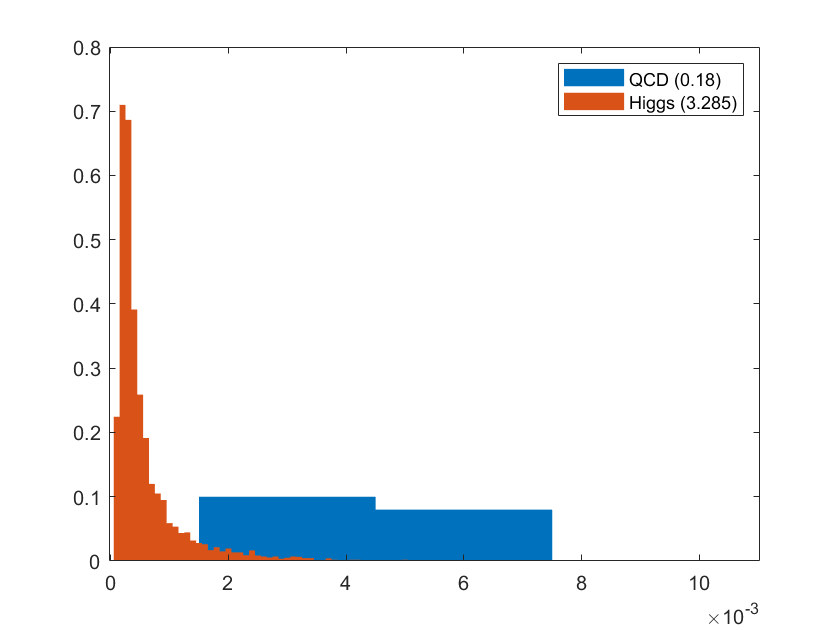

newcutsignal = signaldata1;
newcutbg = bgdata1;
lowercut = 124.99;
uppercut = 125.01;
for k = 1:numel(bgdata1(4,:))
    if signaldata1(4,k) > uppercut || signaldata1(4,k) < lowercut
        newcutsignal(:,k) = nan;
    end
    if bgdata1(4,k) > uppercut || bgdata1(4,k) < lowercut
        newcutbg(:,k) = nan;
    end
end

for k = 1:14   
    signal = newcutsignal(k,:);
    bg = newcutbg(k,:);
    f1 = figure();
    f2 = figure("Visible","off");
    h = histogram(signal,"Normalization","pdf");
    h.BinCounts = h.BinCounts/sum(h.BinCounts) * nhiggs;
    hold on;
    h2 = histogram(bg,"Normalization","pdf");
    h2.BinCounts = h2.BinCounts/sum(h2.BinCounts) * nqcd;
    hold off;
        
    figure(f1);
    bar(h2.BinEdges(2:end),h2.BinCounts,"Edgecolor","none","BarWidth",1);
    hold on;
    bar(h.BinEdges(2:end),h.BinCounts,"Edgecolor","none","BarWidth",1);
    legend("QCD (" + nqcd + ")","Higgs (" + nhiggs + ")");
    hold off;
end

Running into the same issues when things are too small. Not enough background to work with. Some plots show background centered away which can be cut further while preserving much of the true Higgs distribution, but at this point removing more gets us closer to removing the background entirely which doesn't make sense and would cause division by zero for our n over root n calculation we've been doing. Something is clearly wrong with this approach.

## Problem 4

Using multiple features may not be necessary because when we've cut the background down to such a narrow region around mass 125 MeV the events are very likely (7.5-ish) to be the signal.